# **Trading with AI Model**

## Load EURUSD tick data

load('EURUSD');

## Create Predictors & Response

[X,y] = createTechnicalSignalandResponse(prices,false);

## Create Data subset

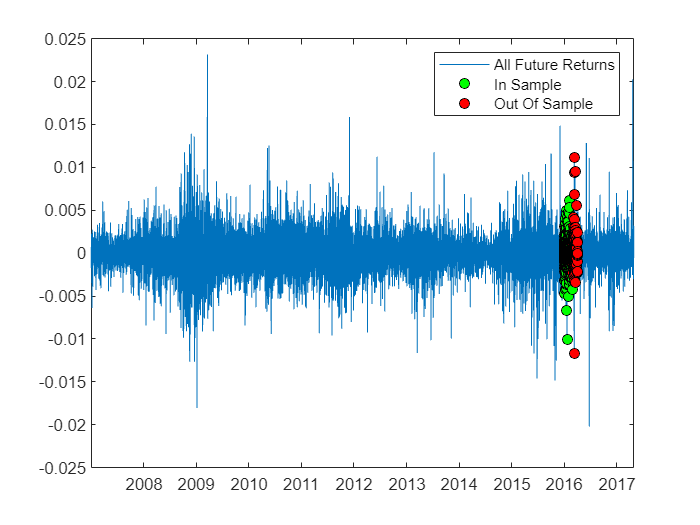

%% Year to Extract
Year = '2016';

[timeIn,XpredictorsIn,yResponseIn]    = createDataSample(X,y,[Year '-01-01'] , [Year '-02-28']);
[timeOut,XpredictorsOut,yResponseOut] = createDataSample(X,y,[Year '-03-01'] , [Year '-03-31']);
figure; plot(X.Time,y.FutureReturn); hold on; plot(timeIn,yResponseIn.FutureReturn,'ko','MarkerFaceColor','green');
plot(timeOut,yResponseOut.FutureReturn,'ko','MarkerFaceColor','red');
legend('All Future Returns','In Sample','Out Of Sample')

# Model #1: Linear Model

modelLinear             = fitlm([XpredictorsIn yResponseIn] , 'linear')

modelLinear = Linear regression model:
    FutureReturn ~ 1 + Return_5 + Return_10 + Return_15 + Return_20 + Return_25 + Return_30 + Return_60 + macd + rsindex_5 + rsindex_10 + rsindex_15 + rsindex_20 + rsindex_25 + rsindex_30 + rsindex_60

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)     0.00012467    0.00052077      0.2394       0.81085
    Return_5          -0.12603       0.32632    -0.38623       0.69942
    Return_10         0.062122        0.2898     0.21436       0.83031
    Return_15          -0.2517       0.28171    -0.89345       0.37185
    Return_20          0.02338       0.27923     0.08373       0.93329
    Retu

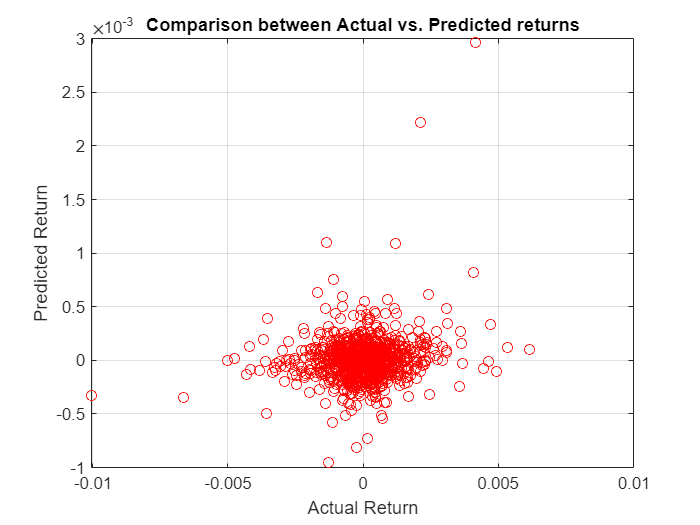


retPredictionRegressIn  = predict(modelLinear , XpredictorsIn);
retPredictionRegressOut = predict(modelLinear , XpredictorsOut);
evaluateScatterPrediction(yResponseIn.FutureReturn,retPredictionRegressIn)

# Model #2: Stepwise Model

modelStepwise            = stepwiselm([XpredictorsIn yResponseIn] , 'linear' , 'upper' , 'linear')

retPredictionStepwiseIn  = predict(modelStepwise , XpredictorsIn);
retPredictionStepwiseOut = predict(modelStepwise , XpredictorsOut);

evaluateScatterPrediction(yResponseIn.FutureReturn,retPredictionStepwiseIn)

## Create Buy/Sell signals for each model

positionsLinearIn    = discretizeBuySellReturn(retPredictionRegressIn);
positionsStepwiseIn  = discretizeBuySellReturn(retPredictionStepwiseIn);
positionsLinearOut   = discretizeBuySellReturn(retPredictionRegressOut);
positionsStepwiseOut = discretizeBuySellReturn(retPredictionStepwiseOut);

## Calculate performance of Linear & Stepwise

Growth100_LinearIn = calculateGrowth(positionsLinearIn,yResponseIn{:,1});
Growth100_LinearOut = calculateGrowth(positionsLinearOut,yResponseOut{:,1});
Growth100_StepwiseIn = calculateGrowth(positionsStepwiseIn,yResponseIn{:,1});
Growth100_StepwiseOut = calculateGrowth(positionsStepwiseOut,yResponseOut{:,1});

% Visualize performance of "In Sample" vs. "Out of Sample"
figure
ax1 = subplot(2,1,1);
plotGrowths(ax1,timeIn,[Growth100_LinearIn Growth100_StepwiseIn],{'Linear','Stepwise'},'In Sample')
ax2 = subplot(2,1,2);
plotGrowths(ax2,timeOut,[Growth100_LinearOut Growth100_StepwiseOut],{'Linear','Stepwise'},'Out of Sample')

# Model #3: Decision tree Model

PredictorTableIn                  = XpredictorsIn;
minimumReturn                     = roundUpTo(nanmedian(prices.Ask - prices.Bid),0.0001);
PredictorTableIn.positionResponse = createPositionOnFutureReturns(yResponseIn.FutureReturn,minimumReturn);
PredictorTableIn.positionResponse = categorical(PredictorTableIn.positionResponse,[-1 0 1],{'Sell' 'Hold' 'Buy'});
modelDecisionTree                 = trainMLTradingModel(PredictorTableIn);
view(modelDecisionTree.ClassificationTree,'mode','graph')

% Calculate performance of Decision tree Model
predictedIn               = modelDecisionTree.predictFcn(PredictorTableIn);
positionsDecisionTreeIn   = convertBuySell2Positions(predictedIn);
Growth100_DecisionTreeIn  = calculateGrowth(positionsDecisionTreeIn,yResponseIn.FutureReturn);

predictedOut              = modelDecisionTree.predictFcn(XpredictorsOut);
positionsDecisionTreeOut  = convertBuySell2Positions(predictedOut);
Growth100_DecisionTreeOut  = calculateGrowth(positionsDecisionTreeOut,yResponseOut.FutureReturn);

## Visualize performance of all models

figure
ax1 = subplot(2,1,1);
plotGrowths(ax1,timeIn,[Growth100_LinearIn Growth100_StepwiseIn Growth100_DecisionTreeIn],{'Linear','Stepwise','Decision Tree'},'In Sample')

ax2 = subplot(2,1,2);
plotGrowths(ax2,timeOut,[Growth100_LinearOut Growth100_StepwiseOut Growth100_DecisionTreeOut],{'Linear','Stepwise','Decision Tree'},'Out of Sample')

# Model #4: Regression Model

PredictorTableIn = XpredictorsIn;
PredictorTableIn.FutureReturn = yResponseIn.FutureReturn;
modelRegressDT = trainRegressionDTModel(PredictorTableIn);
view(modelRegressDT.RegressionTree,'mode','graph')

## Calculate performance of Regression Decision Tree

predictedIn               = modelRegressDT.predictFcn(PredictorTableIn);
positionsDecisionTreeIn   = discretizeBuySellReturn(predictedIn);
Growth100_RegressionDTIn  = calculateGrowth(positionsDecisionTreeIn,yResponseIn.FutureReturn);

predictedOut              = modelRegressDT.predictFcn(XpredictorsOut);
positionsDecisionTreeOut  = discretizeBuySellReturn(predictedOut);
Growth100_RegressionDTOut  = calculateGrowth(positionsDecisionTreeOut,yResponseOut.FutureReturn);

## Visualize performance of all models

figure
ax1 = subplot(2,1,1);
plotGrowths(ax1,timeIn,[Growth100_LinearIn Growth100_StepwiseIn Growth100_DecisionTreeIn Growth100_RegressionDTIn],{'Linear','Stepwise','Decision Tree','Regression Decision Tree'},'In Sample')

ax2 = subplot(2,1,2);
plotGrowths(ax2,timeOut,[Growth100_LinearOut Growth100_StepwiseOut Growth100_DecisionTreeOut Growth100_RegressionDTOut],{'Linear','Stepwise','Decision Tree','Regression Decision Tree'},'Out of Sample')

# Model #5: Neural Network

net = trainNeuralNetwork(XpredictorsIn{:,:},yResponseIn.FutureReturn);
predictedIn = net(XpredictorsIn{:,:}');
positionsNNin   = discretizeBuySellReturn(predictedIn);
Growth100_NNIn  = calculateGrowth(positionsNNin(:),yResponseIn.FutureReturn);

predictedOut = net(XpredictorsOut{:,:}');
positionsNNout   = discretizeBuySellReturn(predictedOut);
Growth100_NNout  = calculateGrowth(positionsNNout(:),yResponseOut.FutureReturn);

## Visualize performance of all models

figure
ax1 = subplot(2,1,1);
plotGrowths(ax1,timeIn,[Growth100_LinearIn Growth100_StepwiseIn Growth100_DecisionTreeIn Growth100_RegressionDTIn Growth100_NNIn],{'Linear','Stepwise','Decision Tree','Regression Decision Tree','Neural Network'},'In Sample')

ax2 = subplot(2,1,2);
plotGrowths(ax2,timeOut,[Growth100_LinearOut Growth100_StepwiseOut Growth100_DecisionTreeOut Growth100_RegressionDTOut Growth100_NNout],{'Linear','Stepwise','Decision Tree','Regression Decision Tree','Neural Network'},'Out of Sample')